# Zr Processing Maps

data = readtable('zr1nb1sn.xlsx');
data.Properties.VariableNames = {'Strain','Strain Rate','T1','T2','T3','T4','T5','T6','T7','T8','T9'}

data = 7×11 table
    Strain    Strain Rate     T1       T2       T3       T4       T5       T6      T7      T8      T9 
    ______    ___________    _____    _____    _____    _____    _____    ____    ____    ____    ____

     NaN           NaN         650      700      750      800      850     900     950    1000    1050
     0.5         0.001         124     74.4     49.7     33.7     17.2    11.8       6     6.5       6
     0.5          0.01       204.6    123.8     81.1     58.4       36    19.2    12.7    11.1     9.8
     0.5           0.1       256.8    174.7    121.4     94.7       57    30.1    19.1    18

data(1,:)=[];

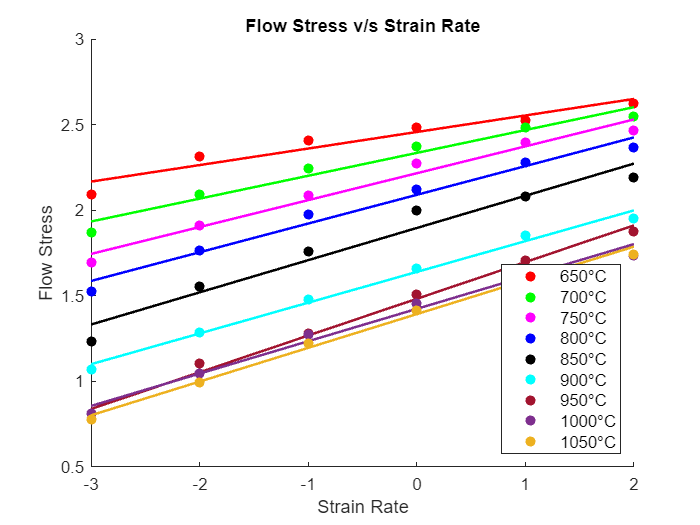

datan= table2array(data);
% 0.5 strain
strain_1 = datan(:,2:end);
sr1 = strain_1(:,1);
strainlog = log10(sr1);
stress1 = strain_1(:,2:end);
y = zeros(6,9);
stresslog = log10(stress1);
C = {'r','g','m','b','k','c',[0.6350 0.0780 0.1840],[0.4940 0.1840 0.5560],[0.9290 0.6940 0.1250]};
hold on
for r = 1:9
    Scatter(r) =scatter(strainlog,stresslog(:,r),'filled','MarkerFaceColor',C{r});
    c= polyfit(log10(sr1),log10(stress1(:,r)),1);
    y(:,r) = polyval(c,log10(sr1));
    plot(log10(sr1),y(:,r),'LineWidth',1.5,'Color',C{r})
end
ylabel('Flow Stress');xlabel('Strain Rate');
title('Flow Stress v/s Strain Rate')
legend(Scatter,'650°C','700°C','750°C','800°C','850°C','900°C','950°C','1000°C','1050°C','Location','southeast','FontSize',10);
hold off

%slope or strain rate sensitivity
%slope or strain rate sensitivity
m= zeros(6,9);
for k =  1:9
 for p = 1:6 
        c1= polyfit(log10(sr1),log10(stress1(:,k)),3);
        deriv = polyder(c1);
        m(p,k) = polyval(deriv,strainlog(p));
 end
end


e= (2*m./(m+1))*100;
T= 650:50:1050;
%instability zone
e1= e/200;
slope= zeros(6,9);
for k =  1:9
    for p =  1:6
        c2= polyfit(log10(sr1),log10(e1(:,k)),3);
        deriv = polyder(c2);
        slope(p,k) = polyval(deriv,strainlog(p));
       
    end
end
iz = slope +m;

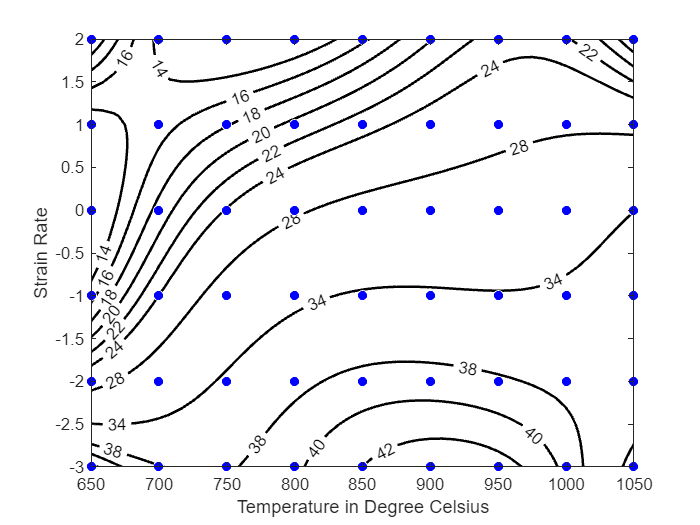

%% Fit: 'untitled fit 1'.
[xData, yData, zData] = prepareSurfaceData( T, strainlog, e );

% Set up fittype and options.
ft = fittype( 'poly45' );

% Fit model to data.
[fitresult] = fit( [xData, yData], zData, ft, 'Normalize', 'on' );

% Make contour plot.
figure( 'Name', 'Power Dissipation' );
h = plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );
% Label axes
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );

grid off
set(h(1),'ShowText','on','LabelSpacing',144)
set(h(1),'LineWidth',1.5,'Fill','off');
set(h(1),'LevelList',[14,16,18,20,22,24,28,34,38,40,42,44,46,48,52])
fig = gcf;
saveas(gcf,'pd.jpg')

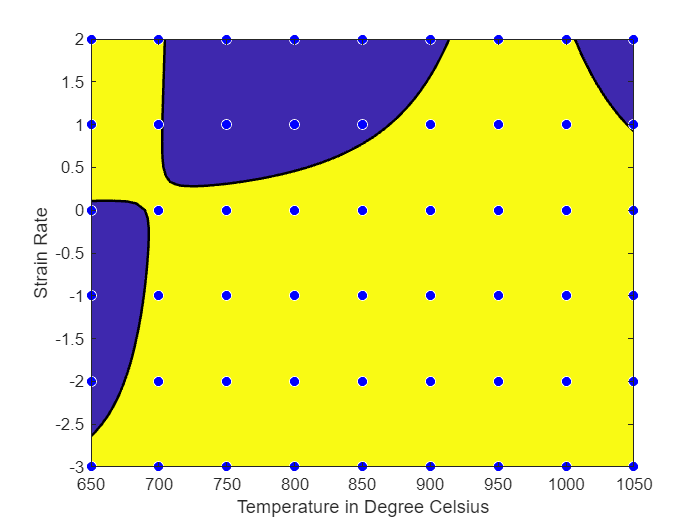


%% Fit: 'untitled fit 2'.
[xData, yData, zData] = prepareSurfaceData( T, strainlog, iz );

% Set up fittype and options.
ft = fittype( 'poly35' );

% Fit model to data.
[fitresult] = fit( [xData, yData], zData, ft, 'Normalize', 'on' );

% Make contour plot.
figure( 'Name', 'untitled fit 2' );
w=plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );
% Label axes
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );
grid off
set(w(1),'LineWidth',1.5,'LevelStep',1);
fig = gcf;
saveas(gcf,'is.jpg')

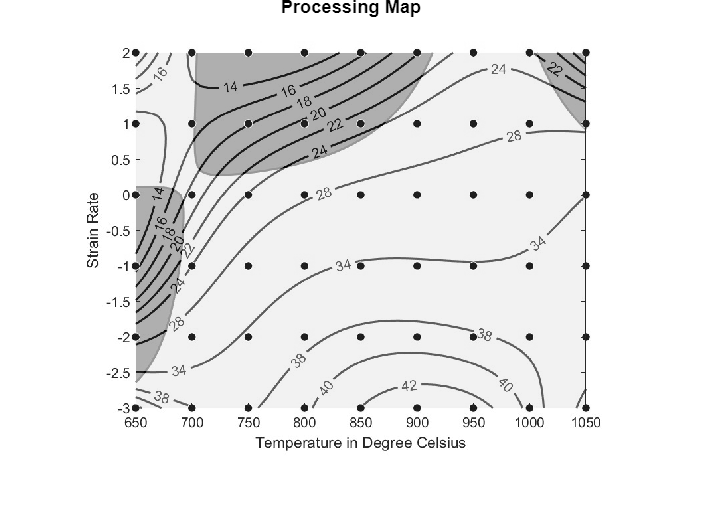

% BASIC IMAGE PROCESSING : SUPERIMPOSE
fig1 = imread('pd.jpg');
fig2 = imread('is.jpg');
fusionimage=imfuse(fig1,fig2,'falsecolor','Scaling','joint');
op=rgb2gray(fusionimage);
imshow(op);
title('Processing Map')